## Main function

Prepare Data and Input 

% Read data symbols and category range

filename = "IDX Stock Symbol Category Market Cap.xlsx";
sheetname = "Latest symbols";
symdbase = readtable (filename,"Sheet", sheetname) ;
A = readtable (filename, "Sheet", "Cap Category Range") ;
capCategRange = sortrows(A,"LB","ascend") ;
clearvars A

% Categorize symbols based on market cap
binEdge = sort (vertcat (capCategRange.LB, 10^6),1,"ascend") ;
CapCategory = discretize (symdbase.MarketCap_InRpTn, binEdge, capCategRange.CapCategory) ;
CapCategory = table (CapCategory) ;
symdbaseT = [symdbase, CapCategory] ;
clearvars symdbase 

% Fetch data from yahoo finance
symList = string(symdbaseT.Symbol);
startdate = '1-Jan-2018';
enddate = datetime ('today');

tStart = tic ;
priceVolumeRaw = getDataYahooIDXPVFcn (symList, startdate, enddate)
tStop = toc(tStart)

% Save priceVolumeRaw
save ("WFATradeData.mat", "priceVolumeRaw");


%% Clean data
tStart = tic ;

% load priceVolumeRaw
load ("WFATradeData.mat", "priceVolumeRaw")
priceVolumeClean = dataCleaningFcn (priceVolumeRaw)
tStop = toc(tStart) 

% Save to matfile for easy access
save ("WFATradeData.mat", "priceVolumeRaw", "priceVolumeClean");


Optimize parameters for WFA

% WFA Preparation and Parameters Settings
paramSetUp

walk_i = 1

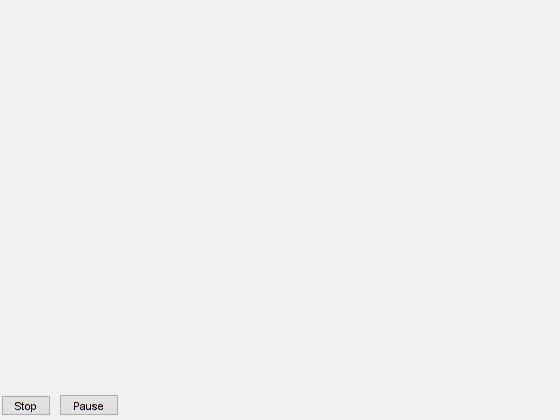

Error using isappdata
Value must be a handle.

Error in callAllOptimPlotFcns (line 97)
    if isappdata(fig,'data')

Error in globaloptim.bmo.BlackboxModelOptimizer/outputAndPlots (

% Optimize parameter for each walk
tStart = tic ;
optimParamsScript ;

tStop = toc(tStart)

% Save Opimtized parameters for WFA
save ("WFATradeData.mat", "priceVolumeRaw", "priceVolumeClean", "paramsStruct")


Conduct WFA on data 

% Preallocate OSTportDailyRetTT 
OSTportDailyRetTT = dataInput.openpriceTT (1,1) ;
OSTportDailyRetTT.Properties.VariableNames = "OSTportDailyRet" ;

% Preallocate netDailyRetperSymTT
sym = string(dataInput.closepriceTT.Properties.VariableNames) ;
sym = eraseBetween (sym, 5,10) ;
nsym = numel(dataInput.openpriceTT.Properties.VariableNames) ;
timecol = NaT(nWalk*nstepOST,1) ;
TT = repmat(timetable(zeros(nWalk*nstepOST,1), 'RowTimes', timecol),1,nsym) ;
TT.Properties.VariableNames = sym ;
OSTnetDailyRetperSymTT = TT ;


Analyze the WFA results

Local functions